close all; clear; clc;

## Cheetah Segmentation with Gaussian Classifier 

In this week, the purpose is the same as last week: cheetah segmentation. The input contains an image with a cheetah and background, and this is taken as a binary classification. In TraningSamples_DCT_8_new, there are traning data labelled by two classes, and the data is discrete cosine transform of similar 8*8 pixels image ordered by zigzag order, which is a matrix with each row represents a 64-dim vector. 

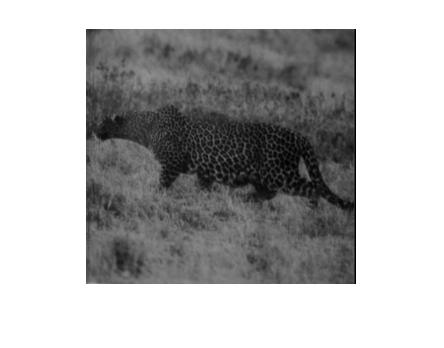

%% Data import
img = imread('cheetah.bmp');
[row,col] = size(img);
imshow(img);

zz_order = dlmread('Zig-Zag Pattern.txt');
load('TrainingSamplesDCT_8_new.mat');
N = 8;

Our goal is to build a Gaussian classifier with maximum likelihood method. Firstly, we can similary calculate prior probabilities of foreground and background by the ratio of training data.

%% Problem 1: Priors

c_size = size(TrainsampleDCT_FG,1);
g_size = size(TrainsampleDCT_BG,1);

Prior_FG = c_size / (c_size + g_size);
Prior_BG = g_size / (c_size + g_size);

disp('Prior probability of cheetah:')

Prior probability of cheetah:


disp(Prior_FG)

    0.1919



disp('Prior probability of grass:')

Prior probability of grass:


disp(Prior_BG)

    0.8081



This result is the same as last week. The prior of cheetah(foreground) is 0.1919 and 0.8081 for grass(background), which indicates an umbalanced ratio between 2 classes. 

Next, we assume that PDF of P(x|class) is Gaussian distribution, which has two parameters: mean(denoted as mu) and variance(denoted as sigma). Because x is a 64-dim vector, these two parameters are in form of multivariate Gaussian. The mean vector along each dimension and covariance matrix are calculated as below. 

mu_FG_64 = mean(TrainsampleDCT_FG);
sigma_FG_64 = std(TrainsampleDCT_FG); % variance along each dim
mu_BG_64 = mean(TrainsampleDCT_BG);
sigma_BG_64 = std(TrainsampleDCT_BG);
cov_BG_64 = cov(TrainsampleDCT_BG);
cov_FG_64 = cov(TrainsampleDCT_FG);

For statistical learning, we need to know which features are better than others. This feature selection can be done by visual inspection: larger the "difference" between two classes, the better this feature is. Marginal density along with each feature, and the best 8 and worst 8 features are found by below:

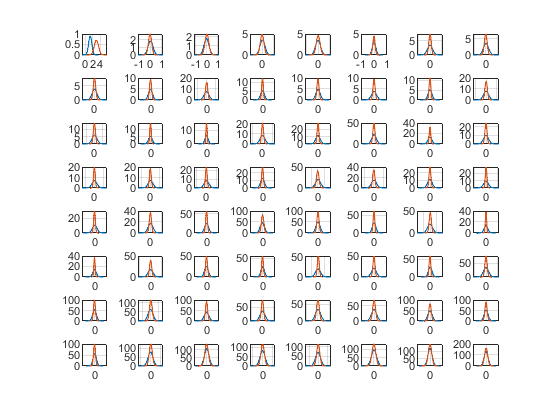

%% Problem 2
figure
for r = 1:N
    for c = 1:N
        subplot(N,N, (r-1) * N + c)
        Gaussian_Plot(mu_FG_64((r-1) * N + c), sigma_FG_64((r-1) * N + c), ...
            mu_BG_64((r-1) * N + c), sigma_BG_64((r-1) * N + c));
    end
end


best8_i = [1:5,40,30,50];
worst8_i = [17,28,29,49,59,60,63,64];

According to MLE for gaussian distribution, P(x|class) can be written as:

#### 
$$P_{X|Y} \left(x|i\right)=\frac{1}{\sqrt{{\left(2\pi \right)}^d \left|\Sigma_i \right|}}\exp \left\lbrace -\frac{1}{2}{\left(x-\mu_i \right)}^T \Sigma^{-1} \left(x-\mu_i \right)\right\rbrace$$


d denotes dim of data, in this case, 64 dim and best 8 dim are used for mask generation. The criterion to assign class to data:

#### 
$$i^* \left(X\right)=\underset{i}{\mathrm{argmax}} \left\lbrack \log P_{X|Y} \left(x|i\right)+\log P_Y \left(i\right)\right\rbrack$$


, e.g. assign class background to such pixel if logP(x|background) + log(P(background)) > logP(x|foreground) + log(foreground). The priors are from problem 1.

%% Class-conditional Distributions: 64 dim
cov_BG_64 = cov(TrainsampleDCT_BG);
cov_FG_64 = cov(TrainsampleDCT_FG);
alpha_BG_64 = (2*pi)^64 * det(cov_BG_64);
alpha_FG_64 = (2*pi)^64 * det(cov_FG_64);
inv_cov_BG_64 = pinv(cov_BG_64);
inv_cov_FG_64 = pinv(cov_FG_64);

%% Class-conditional Distributions: 8 dim
BG_8dim = TrainsampleDCT_BG(:,best8_i);
FG_8dim = TrainsampleDCT_FG(:,best8_i);
mu_FG_8 = mean(FG_8dim);
sigma_FG_8 = std(FG_8dim);
mu_BG_8 = mean(BG_8dim);
sigma_BG_8 = std(BG_8dim);
cov_BG_8 = cov(BG_8dim);
cov_FG_8 = cov(FG_8dim);
alpha_BG_8 = (2*pi)^8 * det(cov_BG_8);
alpha_FG_8 = (2*pi)^8 * det(cov_FG_8);
inv_cov_BG_8 = pinv(cov_BG_8);
inv_cov_FG_8 = pinv(cov_FG_8);

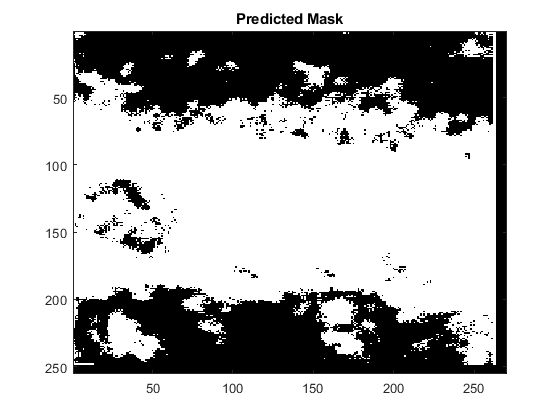

%% Problem 3: Mask Generation

% 64 dim

img_mask = zeros([row,col]);
% Take left top pixel in a block as origin
% The last N-1 pixels are taken as padding
for r = 1:row-N+1
    for c = 1:col-N+1
        sub_img = img(r:r+N-1, c:c+N-1); % 8*8 block image
        sub_img_DCT = dct2(sub_img); 
        sub_img_vec = DCT_zz(sub_img_DCT, zz_order); % The ouput DCT coefficients vector following zz order
        P_x_given_BG = -0.5 * (sub_img_vec - mu_BG_64) * inv_cov_BG_64 * (sub_img_vec - mu_BG_64)' - 0.5 * log(alpha_BG_64);
        P_x_given_FG = -0.5 * (sub_img_vec - mu_FG_64) * inv_cov_FG_64 * (sub_img_vec - mu_FG_64)' - 0.5 * log(alpha_FG_64);
        P_BG_64 = P_x_given_BG + log(Prior_BG);
        P_FG_64 = P_x_given_FG + log(Prior_FG);
        if(P_FG_64 > P_BG_64)
            img_mask(r,c) = 1;
        end
    end
end

A64 = uint8(img_mask) * 255;
figure
imagesc(A64)
title('Predicted Mask')
colormap(gray(255))

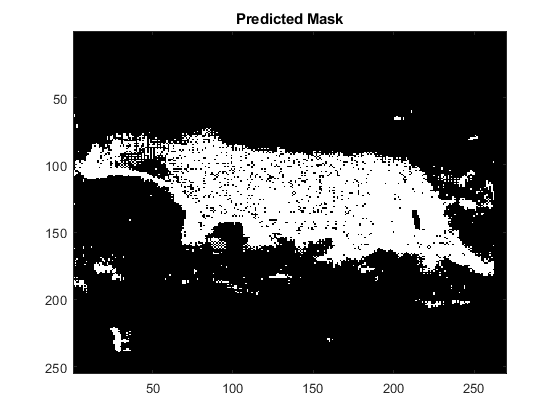


% 8 dim

img_mask = zeros([row,col]);
% Take left top pixel in a block as origin
% The last N-1 pixels are taken as padding
for r = 1:row-N+1
    for c = 1:col-N+1
        sub_img = img(r:r+N-1, c:c+N-1); % 8*8 block image
        sub_img_DCT = dct2(sub_img); 
        sub_img_vec = DCT_zz(sub_img_DCT, zz_order); % The ouput DCT coefficients vector following zz order
        sub_img_vec = sub_img_vec(best8_i);
        P_x_given_BG_8 = -0.5 * (sub_img_vec - mu_BG_8) * inv_cov_BG_8 * (sub_img_vec - mu_BG_8)' - 0.5 * log(alpha_BG_8);
        P_x_given_FG_8 = -0.5 * (sub_img_vec - mu_FG_8) * inv_cov_FG_8 * (sub_img_vec - mu_FG_8)' - 0.5 * log(alpha_FG_8);
        P_BG_8 = P_x_given_BG_8 + log(Prior_BG);
        P_FG_8 = P_x_given_FG_8 + log(Prior_FG);
        if(P_FG_8 > P_BG_8)
            img_mask(r,c) = 1;
        end
    end
end

for i = 1:8
    img_mask(:, col-N+i) = 0;
    img_mask(row-N+i, :) = 0;
end

A8 = uint8(img_mask) * 255;
figure
imagesc(A8)
title('Predicted Mask')
colormap(gray(255))

%% Problem 4: Error Rate
Error_Rate(A64)

Error rate(%):
   39.9332



ans = 39.9332

Error_Rate(A8)

Error rate(%):
    5.7952



ans = 5.7952

In result, we can observe that 8-dim feature vectors can generate more accurate (error rate 5.80%)mask than 64-dim(error rate 39.93%). In 8-dim vector, most 8 representative features are picked for well seperate this two classes. In contrast, 64-dim feature vector may contain more irrelevant or less important information for classification, which brings worse results. The key point is frequency components in DCT: some parts in cheetah's body have smaller spectral energy, which is similar to uniform pattern in background. If we used such features to segment cheetah, the Gaussian classifier would make mistake due to these two "similar" distribution. This difference is consistent with my criteria in picking best 8 features: two distributions must be "far away" from each other. This result indicates the importance of feature selection in statistical leaning. 